StoreStress = zeros(3,controlstep+1);
StoreStrain = zeros(3,controlstep+1);
StoreD = zeros(2,controlstep+1);

cauchy_position = [-sqrt(1/3) sqrt(1/3)]

cauchy_position =    -0.5774    0.5774



for i=1:controlstep+1
    U=StoreU(:,:,i);

    Na_mat = [Na([-1,-1],cauchy_position) Na([1,-1],cauchy_position) Na([1,1],cauchy_position) Na([-1,1],cauchy_position)];

    StoreD(:,i) = (Na_mat*U)';

    [Na_X, J_cauchy] = Finite_Derivative(nodel_position,cauchy_position);

    [F, J] = Finite_Deformation(Na_X,U);

    [P, S, Cmat] = Finite_Stress_Tangent(F, J);

    E = 0.5*(F'*F-eye(2));

    sigma = 1/J*P*F';

    StoreStress(:,i) = [sigma(1,1); sigma(2,2); 0.5*(sigma(1,2)+sigma(2,1))];
    StoreStrain(:,i) = [E(1,1); E(2,2); 0.5*(E(1,2)+E(2,1))];

end

% Residual
f1=figure

f1 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


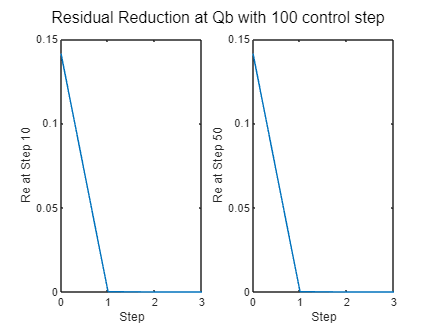

subplot(1,2,1)
plot(0:Step_10-1,StoreRe_10(1:Step_10))
xlabel('Step')
ylabel('Re at Step 10')
subplot(1,2,2)
plot(0:Step_50-1,StoreRe_50(1:Step_50))
xlabel('Step')
ylabel('Re at Step 50')
sgtitle(['Residual Reduction at Qb with 100 control step'])

% d time
f2=figure

f2 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


n = size(StoreD,2)

n = 101

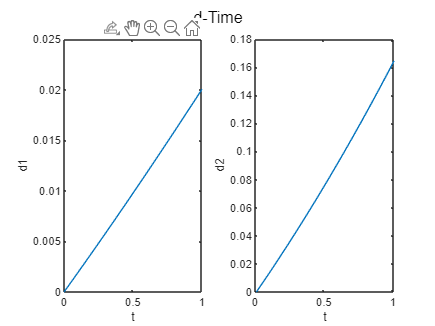

subplot(1,2,1)
plot((0:n-1)/(n-1), StoreD(1,:))
xlabel('t')
ylabel('d1')
subplot(1,2,2)
plot((1:n)/(n-1), StoreD(2,:))
xlabel('t')
ylabel('d2')
sgtitle(['d-Time'])

% Stress time
f3=figure

f3 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


n = size(StoreStress,2)

n = 101

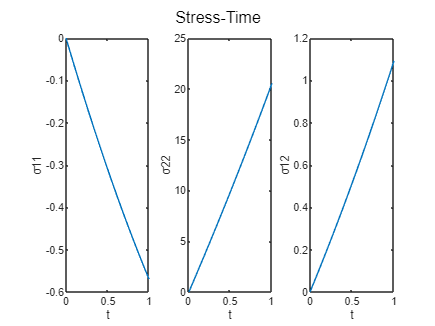

subplot(1,3,1)
plot((0:n-1)/(n-1), StoreStress(1,:))
xlabel('t')
ylabel('σ11')
subplot(1,3,2)
plot((1:n)/(n-1), StoreStress(2,:))
xlabel('t')
ylabel('σ22')
subplot(1,3,3)
plot((0:n-1)/(n-1), StoreStress(3,:))
xlabel('t')
ylabel('σ12')
sgtitle(['Stress-Time'])

% Stress Strain
f4=figure

f4 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


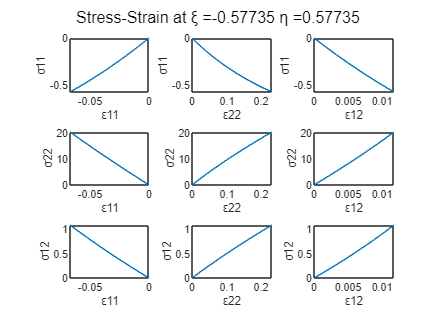

subplot(3,3,1)
plot(StoreStrain(1,:),StoreStress(1,:))
xlabel('ε11')
ylabel('σ11')
subplot(3,3,2)
plot(StoreStrain(2,:),StoreStress(1,:))
xlabel('ε22')
ylabel('σ11')
subplot(3,3,3)
plot(StoreStrain(3,:),StoreStress(1,:))
xlabel('ε12')
ylabel('σ11')

subplot(3,3,4)
plot(StoreStrain(1,:),StoreStress(2,:))
xlabel('ε11')
ylabel('σ22')
subplot(3,3,5)
plot(StoreStrain(2,:),StoreStress(2,:))
xlabel('ε22')
ylabel('σ22')
subplot(3,3,6)
plot(StoreStrain(3,:),StoreStress(2,:))
xlabel('ε12')
ylabel('σ22')

subplot(3,3,7)
plot(StoreStrain(1,:),StoreStress(3,:))
xlabel('ε11')
ylabel('σ12')
subplot(3,3,8)
plot(StoreStrain(2,:),StoreStress(3,:))
xlabel('ε22')
ylabel('σ12')
subplot(3,3,9)
plot(StoreStrain(3,:),StoreStress(3,:))
xlabel('ε12')
ylabel('σ12')

sgtitle(['Stress-Strain at ', 'ξ =',num2str(cauchy_position(1)), ' η =',num2str(cauchy_position(2))])

function [Na]=Na(nodal_position, cauchy_position)
cauchy=cauchy_position(1);
yita=cauchy_position(2);
cau=nodal_position(1);
yi=nodal_position(2);
Na=0.25*(1+cau*cauchy)*(1+yi*yita);
end